

train_x_len = 20;
test_x_len = 10;
num_class = 10;
topLevelFolder = 'DatasetDynGesta'; % or whatever, such as 'C:\Users\John\Documents\MATLAB\work'
% Get a list of all files and folders in this folder.
files = dir(topLevelFolder);
% Get a logical vector that tells which is a directory.
dirFlags = [files.isdir];
% Extract only those that are directories.
subFolders = files(dirFlags); % A structure with extra info.
% Get only the folder names into a cell array.
subFolderNames = {subFolders(3:end).name}; % Start at 3 to skip . and ..

% in_folders = cell2mat(subFolderNames)
in_folders = string(subFolderNames);
n_folds = length(in_folders);



XTrain = [];
YTrain = [];
XTest = [];
YTest = [];
class_idx = [8 5 4 9 1 7 6 3 2 0];
for folds_ixd = 1:n_folds
    files_path = strcat(in_folders(folds_ixd),'\');
    files = dir(fullfile(topLevelFolder,files_path,'*.txt'));
    for file_idx = 1:length(files)
            file_name = fullfile(topLevelFolder,files_path, files(file_idx).name);
            data = dlmread(file_name, ';');
            data_x = data(:,1)-min(data(:,1));
            data_y = abs(data(:,2)-max(data(:,2)));
            data(:,1) = data_x;
            data(:,2) = data_y;
            cel_data(file_idx,1) =num2cell(data', [1 2]); 
    end
    XTrain = [XTrain; cel_data(randi([1 length(files)], [train_x_len 1]))];
    XTest = [XTest; cel_data(randi([1 length(files)], [test_x_len 1]))];
    YTrain = [YTrain, linspace(class_idx(folds_ixd), class_idx(folds_ixd), train_x_len)];
    YTest =[YTest, linspace(class_idx(folds_ixd), class_idx(folds_ixd), test_x_len)];
end


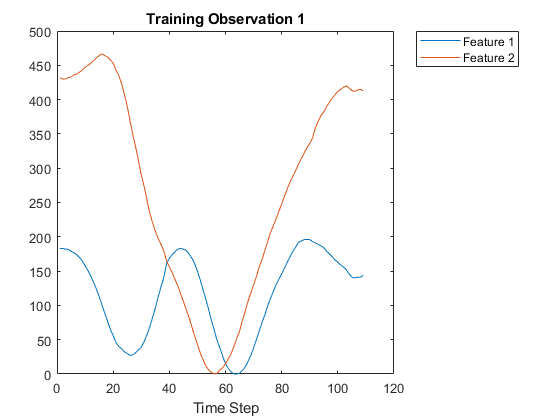

YTrain = categorical(YTrain');
YTest = categorical(YTest');

figure
plot(XTrain{1}')
xlabel("Time Step")
title("Training Observation 1")
numFeatures = size(XTrain{1},1);
legend("Feature " + string(1:numFeatures),'Location','northeastoutside')

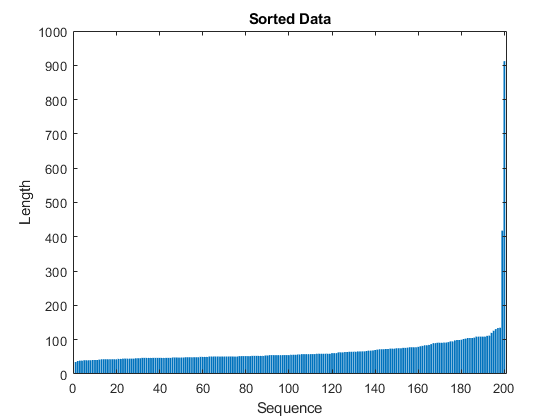


numObservations = numel(XTrain);
for i=1:numObservations
    sequence = XTrain{i};
    sequenceLengths(i) = size(sequence,2);
end


[sequenceLengths,idx] = sort(sequenceLengths);
XTrain = XTrain(idx);
YTrain = YTrain(idx);

figure
bar(sequenceLengths)
% ylim([0 30])
xlabel("Sequence")
ylabel("Length")
title("Sorted Data")


miniBatchSize = 27;

inputSize = 2;
numHiddenUnits = 100;
numClasses = 10;

layers = [ ...
    sequenceInputLayer(inputSize)
    bilstmLayer(numHiddenUnits,'OutputMode','last')
    fullyConnectedLayer(numClasses)
    softmaxLayer
    classificationLayer]

layers =   5×1 Layer array with layers:

     1   ''   Sequence Input          Sequence input with 2 dimensions
     2   ''   BiLSTM                  BiLSTM with 100 hidden units
     3   ''   Fully Connected         10 fully connected layer
     4   ''   Softmax                 softmax
     5   ''   Classification Output   crossentropyex

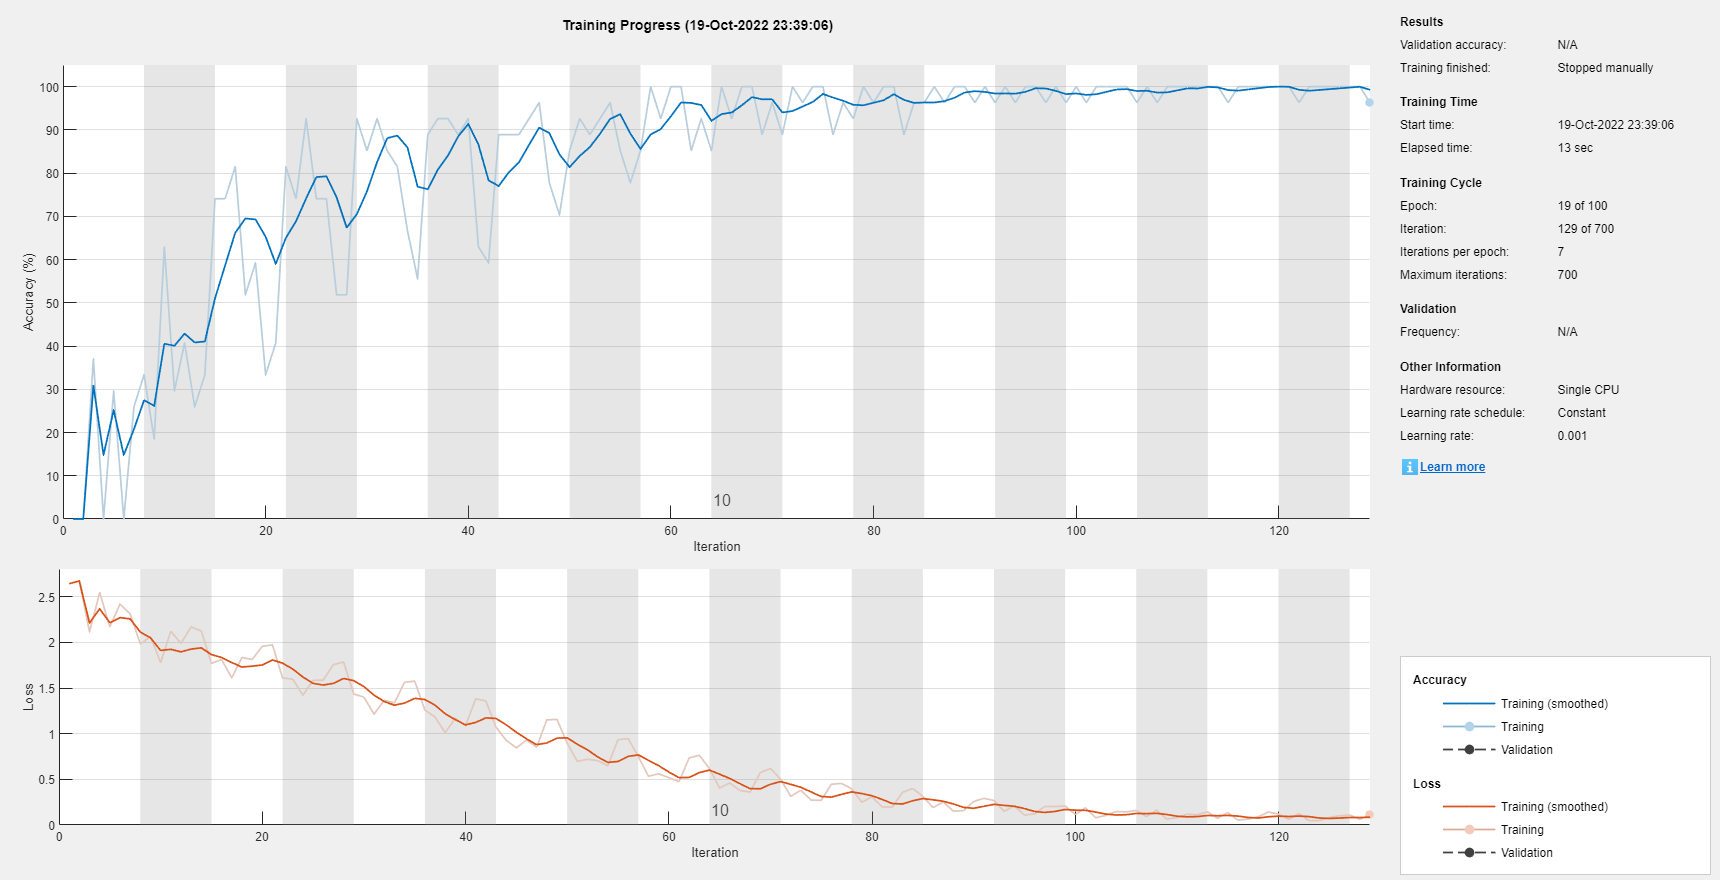


maxEpochs = 100;
miniBatchSize = 27;

options = trainingOptions('adam', ...
    'ExecutionEnvironment','cpu', ...
    'GradientThreshold',1, ...
    'MaxEpochs',maxEpochs, ...
    'MiniBatchSize',miniBatchSize, ...
    'SequenceLength','longest', ...
    'Shuffle','never', ...
    'Verbose',0, ...
    'Plots','training-progress');

net = trainNetwork(XTrain,YTrain,layers,options);


% [XTest,YTest] = japaneseVowelsTestData;
% XTest(1:3)

numObservationsTest = numel(XTest);
for i=1:numObservationsTest
    sequence = XTest{i};
    sequenceLengthsTest(i) = size(sequence,2);
end
[sequenceLengthsTest,idx] = sort(sequenceLengthsTest);
XTest = XTest(idx);
YTest = YTest(idx);

miniBatchSize = 27;
YPred = classify(net,XTest, ...
    'MiniBatchSize',miniBatchSize, ...
    'SequenceLength','longest');

acc = sum(YPred == YTest)./numel(YTest)

acc =                       0.91
